# Robotics 2 20 06 5

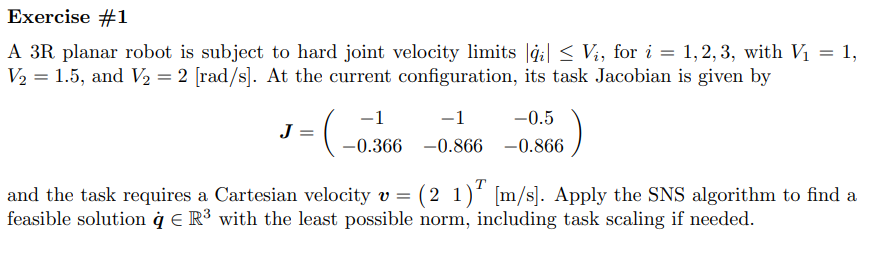

clear all; clc;close all;
V_=[2,1]'

V_ =      2
     1


q_dMax_ = [1,1.5,2] % Maximum acceleration constraints of joints

q_dMax_ =     1.0000    1.5000    2.0000


% 
q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints

q_dMaxTemp_ =     1.0000    1.5000    2.0000


% V_=[0,10]'
qnum = 3; %Number of joints
q = sym('q', [1 qnum],'real');
d = sym('d', [1 qnum],'real');
a = sym('a', [1 qnum],'real');
% 
L = sym('l','real')

$$L = l$$

L_=2

L_ = 2

% % a, alpha, 
R3Robot = [L 0 0 q(1);
           L 0 0 q(2);
%            L 0 0 q(3);
           L 0 0 q(3)]

$$R3Robot = \left(\begin{array}{cccc} l & 0 & 0 & q_{1}\\ l & 0 & 0 & q_{2}\\ l & 0 & 0 & q_{3} \end{array}\right)$$

%        
T0_EE = getTransformationMatrix(R3Robot)

$$T0\_EE = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & 0 & l\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & 0 & l\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% 
% % Calculate the Jacobian (Rotational)
config = 'RRR';
[Jp, Jo,Jps, Jos] = getJacobian(R3Robot,config)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$Jo = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

$$Jps = \left(\begin{array}{ccc} -l\,\left(s_{1}+s_{1,2}+s_{1,2,3}\right) & -l\,\left(s_{1,2}+s_{1,2,3}\right) & -l\,s_{1,2,3}\\ l\,\left(c_{1}+c_{1,2}+c_{1,2,3}\right) & l\,\left(c_{1,2}+c_{1,2,3}\right) & c_{1,2,3}\,l\\ 0 & 0 & 0 \end{array}\right)$$

$$Jos = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

% %Jac = [Jp;Jo]
% %Eliminate the zero rows, which represent the unused variables
Jp = Jp(~all(Jp == 0,2),:)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

% 
q_ = [pi/4,pi/4, pi/3]

q_ =     0.7854    0.7854    1.0472



% J_ = subs(Jp, [q L], [q_ L_])
J_ =sym([-1 -1 -0.5;-0.366 -0.866 -0.866])

$$J\_ = \left(\begin{array}{ccc} -1 & -1 & -\frac{1}{2}\\ -\frac{183}{500} & -\frac{433}{500} & -\frac{433}{500} \end{array}\right)$$

% digits(5)
% vpa(J_)
rank_J_=rank(J_)

rank_J_ = 2

rank_V_=rank(V_)

rank_V_ = 1

if(rank_J_<2)
disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
if(rank_J_==rank_V_)
disp("but The rank is inside of rank V_ all are: "+rank_J_)
disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
end
end

abs_on=true;
autodetectsign=true

autodetectsign = logical
   1


 [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)

qdotPS =    -1.3357
   -0.7384
    0.1481


qdotstar =    -1.3357
   -0.7384
    0.1481


negativeslocales = 3×1 logical array
   1
   1
   0


converting q_dot as negative PAY ATTENTION!!!!! abs=false also


abs_on = logical
   0


q_dMax_ =    -1.0000
   -1.5000
   -2.0000


Max value that violates is:  1  with value:  0.33571
SNS Iterarion:  1


$$ans = \left(\begin{array}{c} 1.0\\ 0.634 \end{array}\right)$$

Jtemp #:  1


$$Jtemp = \left(\begin{array}{cc} -1 & -\frac{1}{2}\\ -\frac{433}{500} & -\frac{433}{500} \end{array}\right)$$

Jtemp pseudo inverse #:  1


$$psJ\_ = \left(\begin{array}{cc} -2.0 & 1.1547344110854503464203233256351\\ 2.0 & -2.3094688221709006928406466512702 \end{array}\right)$$

qdot_components =    -1.2679    0.5358


qdot_sns =    -1.2679
    0.5358


[INFO] No values are exceeding the limits.
Result:


qdotstarFinal =    -1.0000
   -1.2679
    0.5358


qdotstarFinal =    -1.0000
   -1.2679
    0.5358



[qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)

Assuming qN positive if it is not in this way comment this line  PAY ATTENTION!


n = 3

Violatedvalue = logical
   1


SNS Iterarion:  1
The valued that violate are:  "1"  with values:  "-2061151/1807956"
Actual Most Critical Join is:  1
Actual Scaling factor is:  2161717/2414912


$$qdotstar = \left(\begin{array}{c} -\frac{2061151}{1807956}\\ -\frac{1892923}{1807956}\\ \frac{169081}{451989} \end{array}\right)$$

Result:


$$qdotstar = \left(\begin{array}{c} -1\\ -\frac{549}{433}\\ \frac{232}{433} \end{array}\right)$$

$$qdotstarFinal = \left(\begin{array}{c} -1\\ -\frac{549}{433}\\ \frac{232}{433} \end{array}\right)$$

W =      0     0     0
     0     1     0
     0     0     1



vpa(qdotstarFinal)

$$ans = \left(\begin{array}{c} -1.0\\ -1.2678983833718244803695150115473\\ 0.53579676674364896073903002309469 \end{array}\right)$$

pd2_=vpa(J_)*qdotstarFinal

$$pd2\_ = \left(\begin{array}{c} 2.0\\ 1.0 \end{array}\right)$$

vpa(norm(qdotstarFinal))

$$ans = 1.7013654768478859013298415734717$$

## 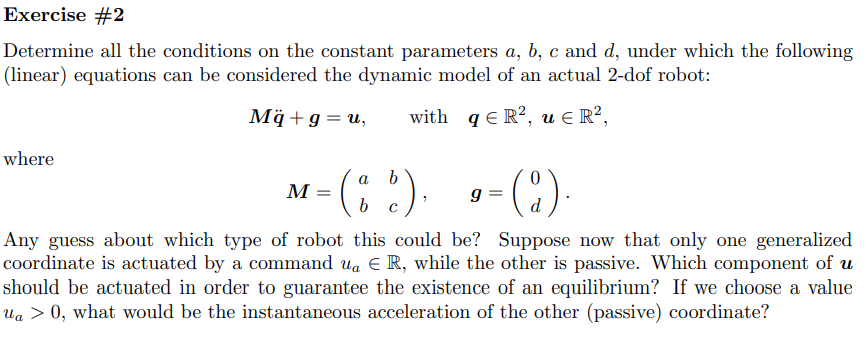

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

defining z struct

% R2Robot=['pp';'xx';sigma ]   ;    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real');
% % z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end
% 

% % % R2Robot=['rr';'x~']       
% xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% z.angle_=[0,alpha_angle]
% % [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,1,[],[],'alpha',false,angle_desired)
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% 

## linear parameterization part 1

%  [g_subs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[])%l')

## part 2

% % 
%  [Yg, Ygshort] = getLinearParametrization(g_subs,aG)


## exercise 3

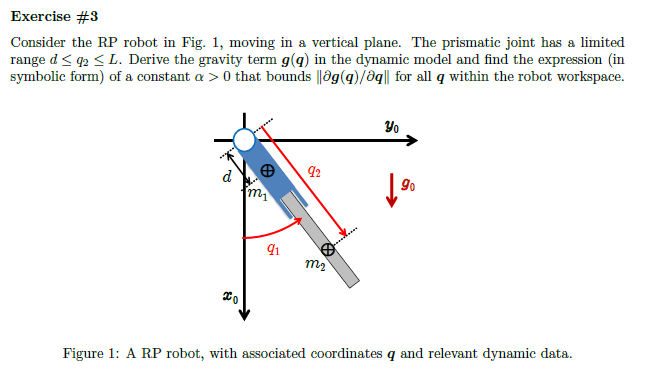

% % This part is isolated from previous section
% clear;clc;
% 
% syms k q1(t) q2(t) q3(t)
% sigma = [0,1];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real'); 
% 
% dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

% g0 = sym('g0','real');
% g=[g0,0,0]';

s

% R2Robot=['rp';'xx';[1,1]]    

R2Robot = 3×2 char array
    'rp'
    'xx'
    ''


% z = Gen_param(n);
% z.sigmaD=R2Robot

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: []
                      l_: []
                       q: []
                   q_dot: []
                      q_: []
                  q_dot_: []
                      dc: []
                       m: []
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0
           vartoderivate: "q

% z.l=l

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: []
                   q_dot: []
                      q_: []
                  q_dot_: []
                      dc: []
                       m: []
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0
           vartoderiv

% z.q=q

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: []
                      q_: []
                  q_dot_: []
                      dc: []
                       m: []
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0
           var

% z.q_dot=qd

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: []
                       m: []
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0
       

% z.dc=dc

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: []
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0


% z.m=m

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: {}
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_o

% z.I=I

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.methodD=1

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.dhTable=[]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.firstParam='alpha'

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.rc=[]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.movingframes=[]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: []
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
             

% z.angle_=sym(zeros(1,n))

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: []
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
             

% z.opt_expr={[l(1)+q(2)],[q(2)]}

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: []
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [1×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismo

% z.rcdefined=true;

% 
%    
% xyonly=true

xyonly = logical
   1


% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% l(1)=0

$$l = \left(\begin{array}{c} 0\\ l_{2} \end{array}\right)$$

% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: []
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [1×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismo

si falla aquí está el error


anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & q_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & {\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & -{\dot{q}}_{1}\\ {\dot{q}}_{1} & 0 \end{array}\right)$$

$$T = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({q_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

% [C,cac,Csubs,S] = getCs(M,q,qd)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} q_{2}\,\left(2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\right)\\ -q_{2}\,\left(m_{2}\,{{\dot{q}}_{1}}^{2}\right) \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S = \left(\begin{array}{cc} q_{2}\,\left(m_{2}\,{\dot{q}}_{2}\right) & q_{2}\,\left(m_{2}\,{\dot{q}}_{1}\right)\\ -q_{2}\,\left(m_{2}\,{\dot{q}}_{1}\right) & 0 \end{array}\right)$$

% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

$$u = \left(\begin{array}{c} q_{2}\,\left(2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\right)+{\ddot{q}}_{1}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)\\ m_{2}\,\left({\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2}\right) \end{array}\right)$$

% isMotor=false

isMotor = logical
   0


% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = -g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)$$

$$PE\_short = -g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)\\ -g_{0}\,m_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)\\ -g_{0}\,m_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

$$PE = -g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)$$

U = 1×2 cell array
    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)\\ -g_{0}\,m_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

$$PE\_short = -g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right)$$

% U{:}

$$ans = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

$$ans = -g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)$$

% lambda_def=Get_A_matrix(g_q,q)

$$p = \left(\begin{array}{ccc} p_{1} & p_{2} & p_{3} \end{array}\right)$$

$$A\_ = \left(\begin{array}{cc} g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+m_{2}\,q_{2}\right) & g_{0}\,m_{2}\,\sin\left(q_{1}\right)\\ g_{0}\,m_{2}\,\sin\left(q_{1}\right) & 0 \end{array}\right)$$

$$A\_square = \left(\begin{array}{cc} a_{1,1} & a_{1,2}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

$$A\_square = \left(\begin{array}{cc} a_{1,1} & a_{2,1}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

$$lambda = \lambda$$

lambda_def = struct with fields:
     lambda1_: [2×1 sym]
     lambda2_: [2×1 sym]
     A_square: [2×2 sym]
    A_square_: [2×2 sym]
           A_: [2×2 sym]


% toreplace=[cos(q(1)),sin(q(1)),q(2)]

$$toreplace = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & q_{2} \end{array}\right)$$

% L=sym('L','real')

$$L = L$$

% toreplace_=[1,1,L]

$$toreplace\_ = \left(\begin{array}{ccc} 1 & 1 & L \end{array}\right)$$

% lambda1_=subs(lambda_def.lambda2_,toreplace,toreplace_)

$$lambda1\_ = \begin{array}{l} \left(\begin{array}{c} {g_{0}}^{2}\,{m_{2}}^{2}+\sigma_{2}+\sigma_{1}-\sigma_{3}-\sigma_{4}+L\,{\mathrm{dc}}_{1}\,{g_{0}}^{2}\,m_{1}\,m_{2}\\ {g_{0}}^{2}\,{m_{2}}^{2}+\sigma_{2}+\sigma_{1}+\sigma_{3}+\sigma_{4}+L\,{\mathrm{dc}}_{1}\,{g_{0}}^{2}\,m_{1}\,m_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{{\mathrm{dc}}_{1}}^{2}\,{g_{0}}^{2}\,{m_{1}}^{2}}{2}\\ \sigma_{2}=\frac{L^{2}\,{g_{0}}^{2}\,{m_{2}}^{2}}{2}\\ \sigma_{3}=\frac{L\,{g_{0}}^{2}\,m_{2}\,\sigma_{5}}{2}\\ \sigma_{4}=\frac{{\mathrm{dc}}_{1}\,{g_{0}}^{2}\,m_{1}\,\sigma_{5}}{2}\\ \sigma_{5}=\sqrt{L^{2}\,{m_{2}}^{2}+2\,L\,{\mathrm{dc}}_{1}\,m_{1}\,m_{2}+{{\mathrm{dc}}_{1}}^{2}\,{m_{1}}^{2}+4\,{m_{2}}^{2}} \end{array}$$

% alpha_=sqrt(lambda1_(1))

$$alpha\_ = \begin{array}{l} \sqrt{{g_{0}}^{2}\,{m_{2}}^{2}+\frac{L^{2}\,{g_{0}}^{2}\,{m_{2}}^{2}}{2}+\frac{{{\mathrm{dc}}_{1}}^{2}\,{g_{0}}^{2}\,{m_{1}}^{2}}{2}-\frac{L\,{g_{0}}^{2}\,m_{2}\,\sigma_{1}}{2}-\frac{{\mathrm{dc}}_{1}\,{g_{0}}^{2}\,m_{1}\,\sigma_{1}}{2}+L\,{\mathrm{dc}}_{1}\,{g_{0}}^{2}\,m_{1}\,m_{2}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{L^{2}\,{m_{2}}^{2}+2\,L\,{\mathrm{dc}}_{1}\,m_{1}\,m_{2}+{{\mathrm{dc}}_{1}}^{2}\,{m_{1}}^{2}+4\,{m_{2}}^{2}} \end{array}$$

% 


## Exercise 4

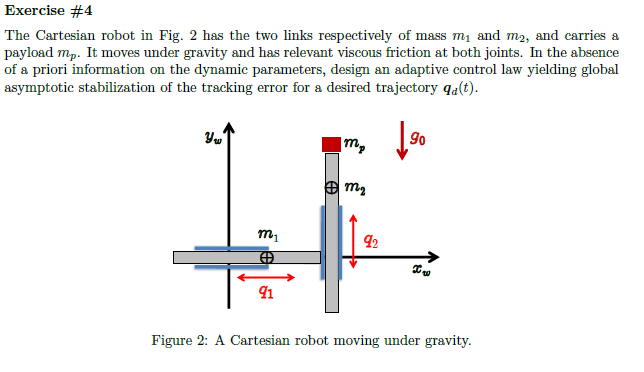

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot_d= sym('q_dot_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

s

% R2Robot=['pp';'xy';[1,1]]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_dot_d=q_dot_d;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;

% 
%    
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);

Viscouz terms

% F_v=sym('F_v',[n,1],'real').*eye(n)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

## get dinamyc paramters

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% % [C,cac,Csubs] = getCs(Msubs,q',qd';)
% u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% 
% Msubs = All(:,1:n)
% gSubs = diag(All(:,n+1:2*n))
% FSubs = All(:,2*n+1:end)

% u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

## Linearization

% Y=sym('Y','real')
% Y_=getLinearParametrization(u_subs,a)

## Adpative control law

% z_u.Y=Y;
% z_u.Y_=Y_;
% z_u.q=q;
% z_u.q_d=q_d%q desired
% z_u.q_dot_d=q_dot_d
% t=sym('t','real');
% q_dots=derivate_D(q_d,n,t,'q_d');
% z_u.q_d_dot =q_dots.dot;
% z_u.q_d_ddot=q_dots.ddot;
% z_u.a=a;
% z_u.n=n;
% z_u.q_dot=q_dot;
% z_u.q_ddot=q_ddot;
% 
% u_control=Adpatative_Control_Law(z_u)
% u_control.Y_r_
% u_control.u
% u_control.u_
% u_control.a_hat_dot
% u_control.a_hat_dot_
% u_control.mq_r_dot %I'm not sure about this
% u_control.q_r_dot_

## 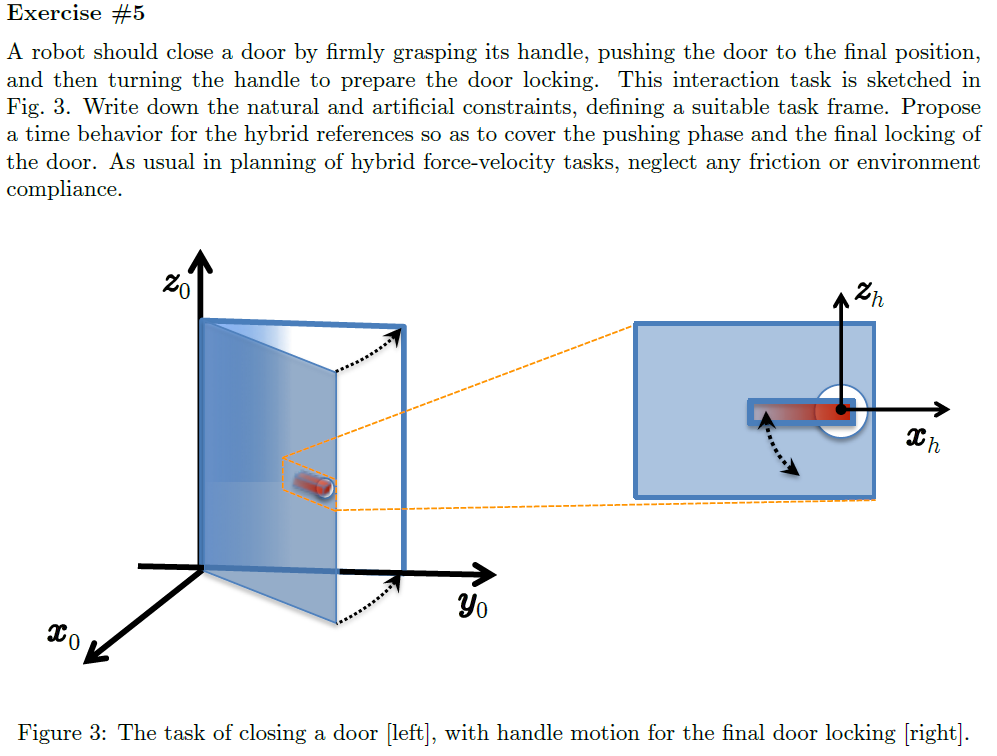

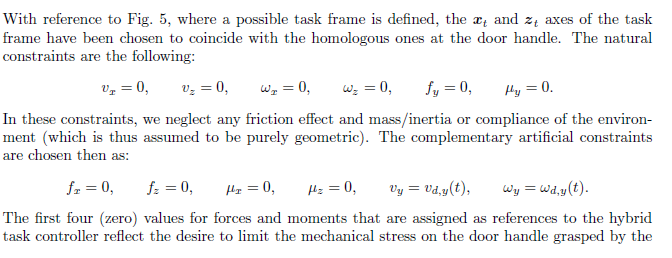

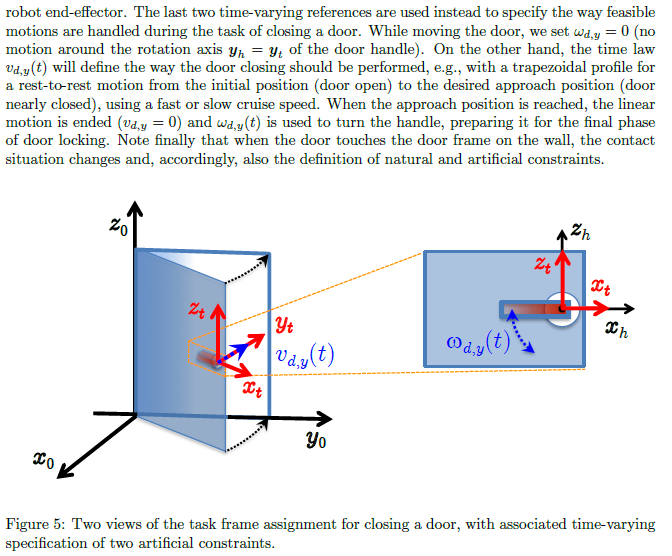

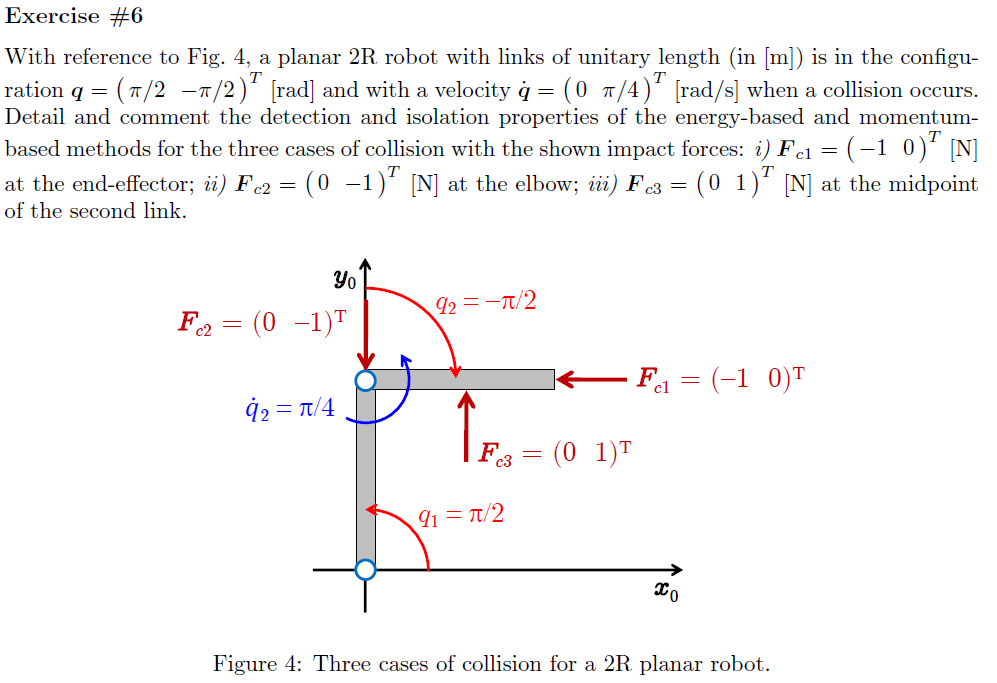

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% g=[0,0,-g0]';
% R2Robot=['rr';'xx';sigma]    
% z = Gen_param(n);
% z.g=g;
% z.g0=g0;
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.l_=[1,1]';
% 
% % z.opt_expr={[l;dc],[z.l_;z.l_/2]};
% % z.rcdefined=true;

## defining collisions

% 
% % collide1=
% z.collides=[struct('F',[-1,0,0]' ,'joint',2,'F_pos',l(2)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(2)

## computing

% 
% % 
% %    
% % % xyonly=true
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% z.q_=[pi/2,-pi/2]';
% z.q_dot_=[0,pi/4]';
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)
% zout.J_c_collisions{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% 
% zout.J_c_collisions_{:}
% zout.vc_collisions_
% zout.Vc_T_dot_Fk_
% zout.Tau_c_
% 
% (z.q_dot_'*zout.Tau_c_)'
% 
% vc_=subs(vc,q,z.q_)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);